# Autocorrelation Functions

## Autocorrelation

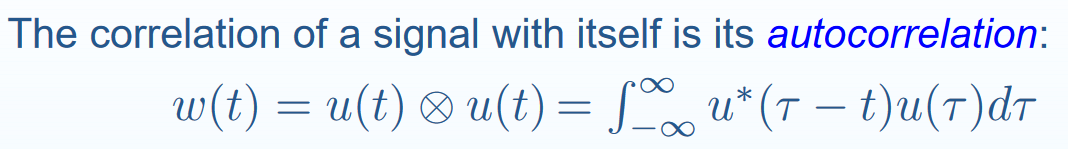

## Cross-correlation

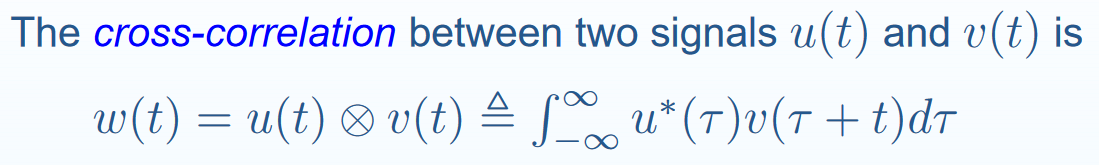

## Details

### Properties of autocorrelation sequence

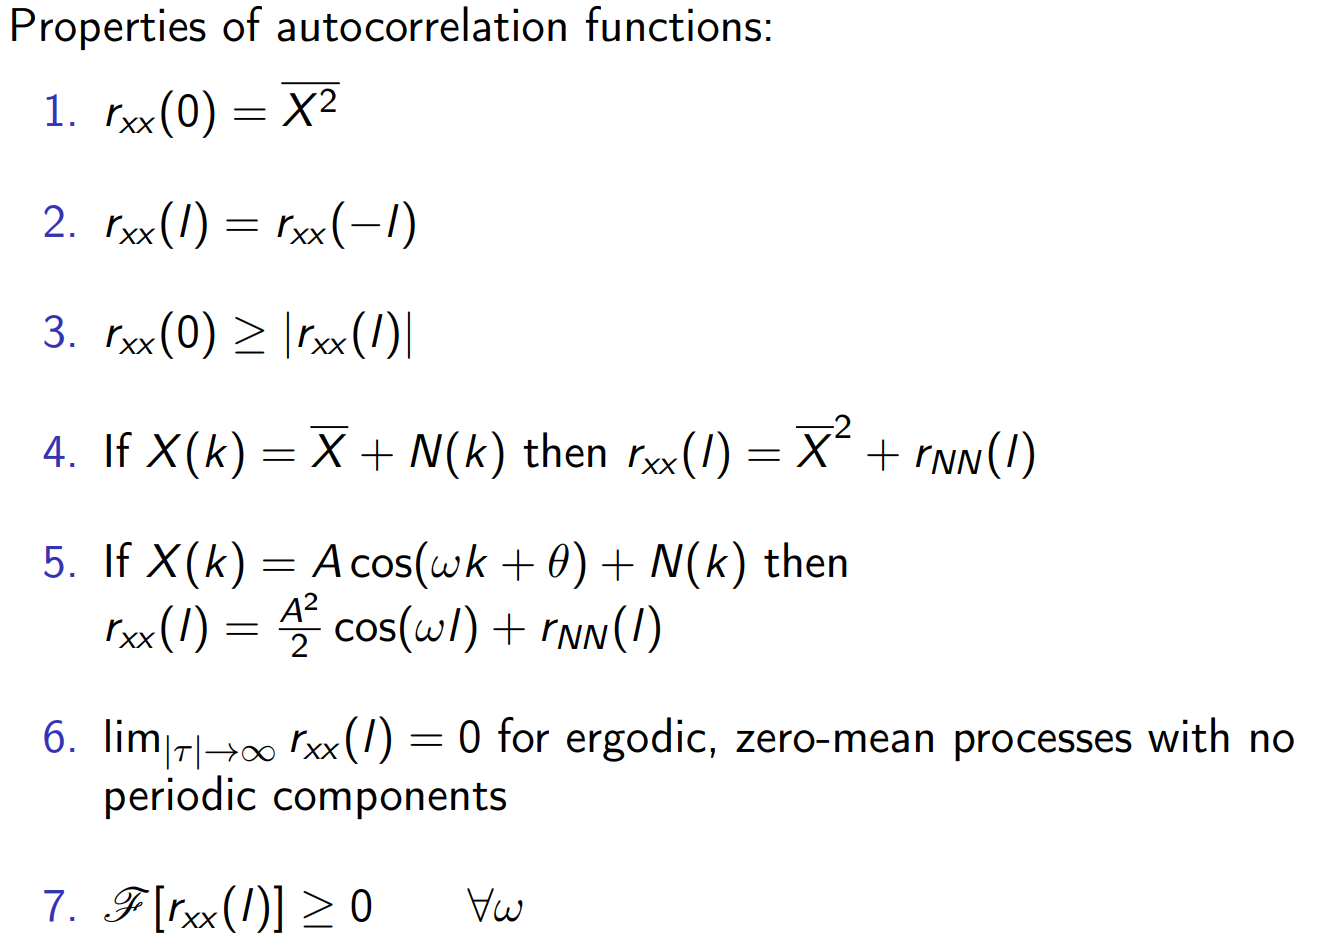

### Fundamental property of autocorrelation r(0) >= r(l)

A fundamental property of the autocorrelation function is that $r_x \left(0\right)\ge r_x \left(\ell \right)$ for all $\ell$. 

### Autocorrelation and cross-correlation of complex signals

The autocorrelation function of a complex signal is given by:

        
$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n-\ell \right)\right\rbrack$$


The cross-correlation function of a complex signal is given by:

        
$$r_{\textrm{yx}} \left(\ell \right)=E\left\lbrack y\left(n\right)x^* \left(n-\ell \right)\right\rbrack$$


### Cross-correlation of two uncorrelated noise processes

Let $v\left(n\right)$ and $w\left(n\right)$ be **two uncorrelated white noise **processes with variance $\sigma_v^2 =0\ldotp 49$ and $\sigma_w^2 =1$. The cross-correlation between these processes is:

        
$$r_{\mathrm{vw}} \left(\ell \right)=0$$


### Relations between r(ell) and r(-ell)

Let us compute the autocorrelation for $-\ell$:

        
$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n+\ell \right)\right\rbrack$$


Suppose $m=n+\ell$. Then we can write $n=m-\ell$. Let us substitute all $n$ with $m$ in the above expression:

        
$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(m-\ell \right)x^* \left(m\right)\right\rbrack$$


Computing the complex conjucate of the expectation we get:

        
$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x^* \left(m-\ell \right)x\left(m\right)\right\rbrack }^*$$


        
$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$$


Since $r_{\textrm{xx}}^* \left(\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$, we know that:

        
$$r_{\textrm{xx}} \left(-\ell \right)=r_{\textrm{xx}}^* \left(\ell \right)$$


### Autocorrelation of complex signal

**Problem: **

What is the autocorrelation function  of the complex sinusoid $x\left(n\right)={A\;e}^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$

**Solution:**

The autocorrelation function for complex signals can be computed as:

        
$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack z\left(n\right)z^* \left(n-\ell \right)\right\rbrack$$


Plugging the given complex sinusiod into the formula, we get:

        
$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack A\;e^{j\left(\omega n+\phi \right)} A\;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$


Since $A$ is a constant, we can move it outside the expected value:

        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\left(\omega n+\phi \right)} \;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$


        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi } \;e^{-j\omega n+j\omega \ell -j\phi } \right\rbrack$$


        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi +\left(-j\omega n+j\omega \ell -j\phi \right)} \;\right\rbrack$$


        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi -j\omega n+j\omega \ell -j\phi } \;\right\rbrack$$


        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega \ell } \;\right\rbrack$$


We know that $E\left\lbrack e^{j\omega \ell } \right\rbrack =e^{j\omega \ell }$ because the expected value of a constant is just the constant itself. Notice that $\phi$ is no longer in the expression $e^{j\omega \ell }$. Therefore, the autocorrelation of the complex sinusoid is:

        
$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Thus, the autocorrelation of the complex sinusoid $z\left(n\right)={A\;e}^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is given by:

        
$$r_{\mathrm{zz}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


### Autocorrelation of a real cosine signal

**Problem: **

What is the autocorrelation function of a real signal $x\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$?

**Solution:**

In ADSI Problem 4.4.1, we know that the autocorrelation of the complex sinusoid $z\left(n\right)={A\;e}^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is given by:

        
$$r_{\mathrm{zz}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Since the result from 1) uses Euler, we need to convert the signal to complex exponential. 

We use the relation $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$

        
$$x\left(n\right)=A\;\mathrm{cos}\left(\omega \;n+\phi \right)$$


        
$$x\left(n\right)=\frac{A}{2}\;\left(e^{j\left(\omega n+\phi \right)} +e^{-j\left(\omega n+\phi \right)} \right)$$


        
$$x\left(n\right)=\frac{A}{2}e^{j\left(\omega n+\phi \right)} +\frac{A}{2}e^{-j\left(\omega n+\phi \right)}$$


In 1) we found that the autocorrelation of a complex sinusoid $x\left(n\right)=A\;e^{j\left(\omega \;n+\phi \right)}$ is $r_{\textrm{xx}} \left(\ell \right)=A^2 e^{j\omega \ell }$

Therefore, the autocorrelation of the real signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)={\left(\frac{A}{2}\right)}^2 e^{j\omega \ell } +{\left(\frac{A}{2}\right)}^2 e^{-j\omega \ell }$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Using the relation $\cos \left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$  we can rewrite the autocorrelation to:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


Thus, the autocorrelation function of a real signal $z\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{zz}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega \ell \right)$$


### Autocorrelation of a real sine signal

**Problem: ** 

What is the autocorrelation function of a real signal $z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$?

**Solution:**

In ADSI Problem 4.4, we found that the autocorrelation of a complex sinusoid given by $y\left(n\right)=A\;e^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=A^2 \;e^{j\omega \ell }$$


To use this result, we need to convert the given signal in this problem to complex exponential signal.

A complex exponential signal is always formed by the sum of two real signals:

        
$$Ae^{j\omega n} =A\;\mathrm{cos}\left(\omega n\right)+j\;A\;\mathrm{sin}\left(\omega n\right)$$


Therefore, we know that:

        
$$\mathrm{sin}\left(\omega \right)=\frac{1}{2j}e^{j\omega } -\frac{1}{2j}e^{-j\omega }$$


Using this relation, we can rewrite a real signal $A\;\mathrm{sin}\left(\omega n+\phi \right)$ as:

        
$$z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$$


        
$$z\left(n\right)=\frac{A}{2j}e^{j\left(\omega n+\phi \right)} -\frac{A}{2j}e^{-j\left(\omega n+\phi \right)}$$


To compute the autocorrelation function, we square the magnitude, remove the phase and replace $n$ with $\ell$:

        
$$r_{\mathrm{zz}} \left(\ell \right)={\left(\frac{A}{2j}\right)}^2 e^{j\omega \ell } -{\left(\frac{A}{2j}\right)}^2 e^{-j\omega \ell }$$


We know that${\left(2j\right)}^2 =2^2 \cdot j^2 =-4$ because $j=\sqrt{-1}$ so $j^2 =-1$

        
$$r_{\textrm{zz}} \left(\ell \right)=\frac{A^2 }{-4}e^{j\omega \ell } -\frac{A^2 }{-4}e^{-j\omega \ell }$$


        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$


We want to make the autocorrelation function in terms of $\mathrm{cos}\left(\cdot \right)$, we rewrite the expression as follows:

        
$$r_{\textrm{zz}} \left(\ell \right)=\left(-\frac{A^2 }{2}\right)\cdot \frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Since $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$, we can rewrite the expression as:

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


Thus, the autocorrelation function of a real signal $z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$ is

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


### Autocorrelation of white noise

White noise is important for random signal modelling. 

Suppose we have a random process that produces perfect random noise.  Let $w\left(n\right)$ be a random signal from this process.

The** expected value** of the signal is zero because there are no patterns in white noise:

        
$$E\left\lbrack w\left(n\right)\right\rbrack =0$$


The **autocorrelation of white noise** generates one peak at $\ell =0$ because that is the only time when there is any correlation of the signal. One peak at $\ell =0$ can be modelled by delta signal:

        
$$r_{\textrm{ww}} \left(\ell \right)=E\left\lbrack w\left(n\right)w\left(n-\ell \right)\right\rbrack$$


                    
$$=\sigma_w^2 \delta \left(\ell \right)$$


where $\sigma_w^2$ is the variance of the signal which can be computed as follow:

        $\begin{array}{l}
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -E{\left\lbrack w\left(n\right)\right\rbrack }^2 \\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -0\\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack 
\end{array}$     (by definition $E\left\lbrack w\left(n\right)\right\rbrack =0$)

### System identification with white noise

`INSIGHT`*:* we can use white noise to find the impulse response of a system because the autocorrelation of white noise is the same the delta signal.

We have an unknown system with an impulse response $h\left\lbrack n\right\rbrack$.

        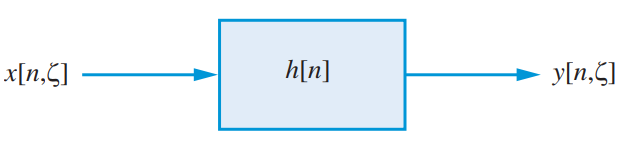

 As input to this system, we give it a zero-mean white noise signal (a realisation of white noise random process):

        
$$x\left(n\right)~\mathrm{WN}\left(0,\sigma_x^2 \right)$$


The cross-correlation between this white noise signal and output of the system is given by Eq. 13.100:

        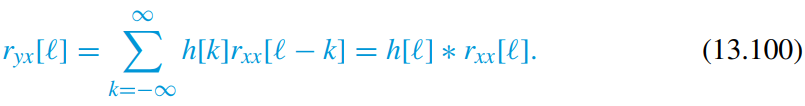

Since $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)$ the convolution becomes:

        
$$r_{\mathrm{yx}} \left(\ell \right)=h\left(\ell \right)*\sigma_x^2 \delta \left(\ell \right)$$


        
$$r_{\textrm{yx}} \left(\ell \right)=\sigma_x^2 h\left(\ell \right)$$


This means that the cross-correlation is just the impulse response.

### High frequency noise vs low frequency noise

We can use the autocorrelation of a noise to determine whether it is low-frequency vs high-frequency.

Plotting the ACRS, we see that the high-frequency noise oscillates whereas the low-frequency noise does not.

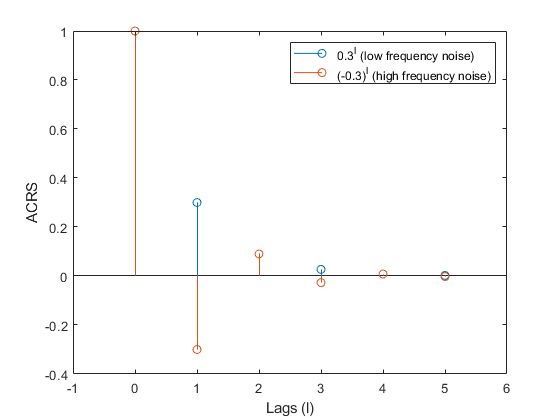

clear variables;
ell = 0:5;

stem(ell, 0.3.^ell)
hold on;
stem(ell, (-0.3).^ell)
hold off;
legend('0.3^l (low frequency noise)', '(-0.3)^l (high frequency noise)')
xlim([min(ell)-1, max(ell)+1])
hold off;
xlabel('Lags (l)')
ylabel('ACRS')

## Problems

## If a signal is scaled by 2, does its autocorrelation also scale by 2?

Answer: FALSE.

The autocorrelation of a signal $x\left(n\right)$ is defined as:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


We can compute the autocorrelation of signal $y\left(n\right)=2x\left(n\right)$ as follows:

        
$$r_y \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=E\left\lbrack 2\;x\left(n\right)2x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4\cdot E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4r_x \left(\ell \right)$$


## How to interpret ACRS estimate of the noise process.

This problem uses the signal file f16.mat that contains **noise** recorded at the co-pilot’s seat of an F-16 airplane using a 16 bit A/D converter with $F_S =19\ldotp 98$ kHz. 

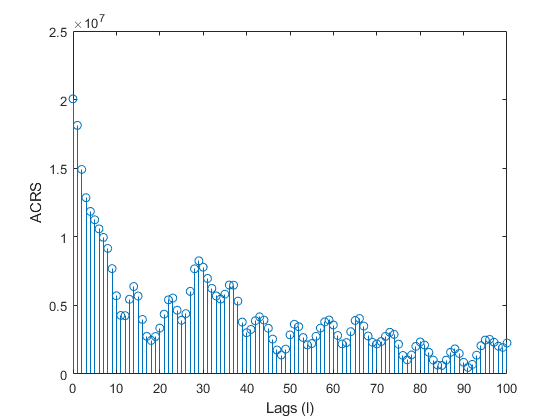

load('f16.mat')
y = f16;
L = 100;

[lags, r_yy] = xcorr(y, L, 'biased');
mid = ceil(numel(r_yy)/2);
stem(r_yy(mid:end), lags(mid:end))
xlabel('Lags (l)')
ylabel('ACRS')

- From the autocorrelation sequence, we see that there is some structure in the signal. The sequence is not decaying smoothly from lag zero to 100.

- The ACRS does not change sign so it seems to be some kind is low-frequency signal

- In order for the ACRS to go from lags zero to 100, it must be some higher-order process AR(p) model. It is definitely not a MA(q) process model.

## [✔] ADSI Problem 4.2: Autocorrelation functions from plot

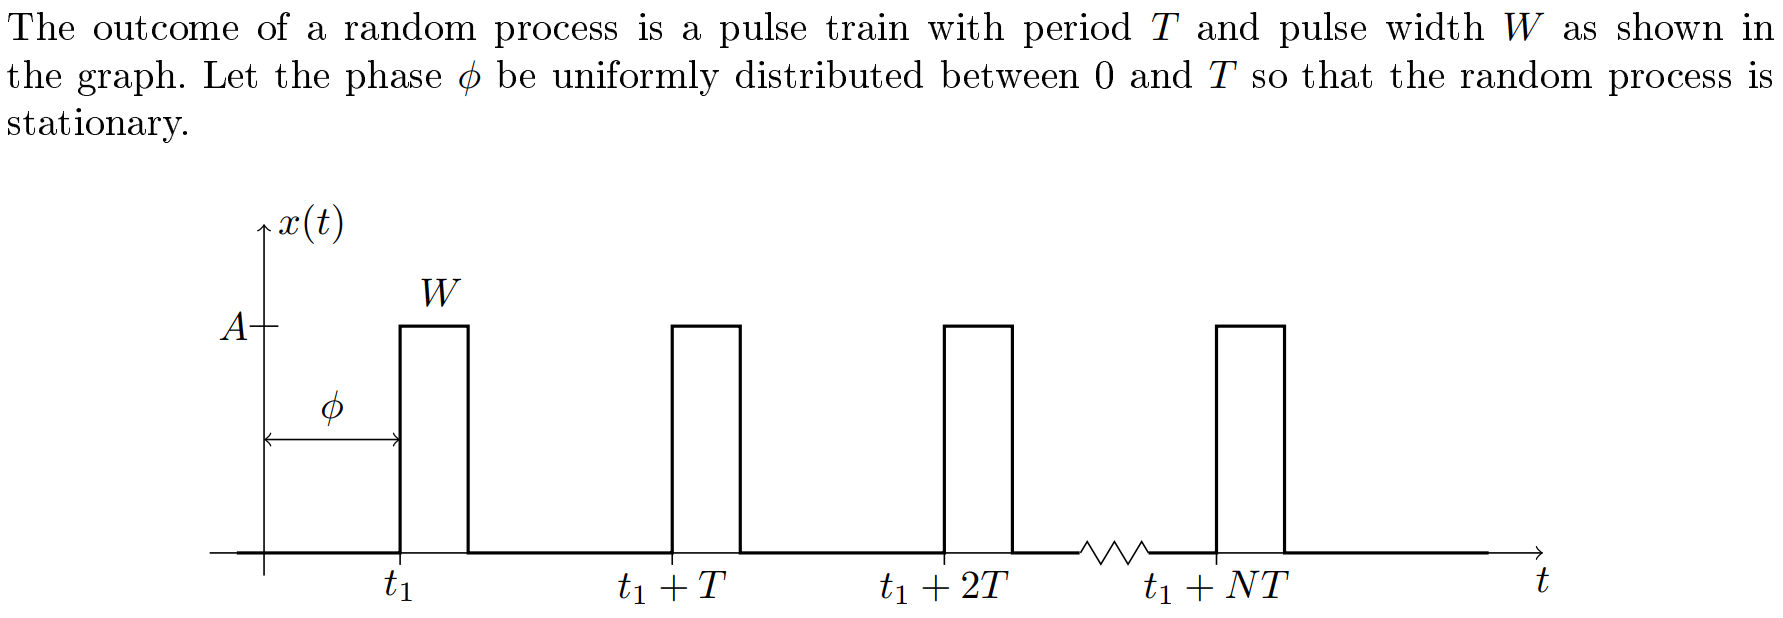

### 1) Sketch and explain what the autocorrelation looks like

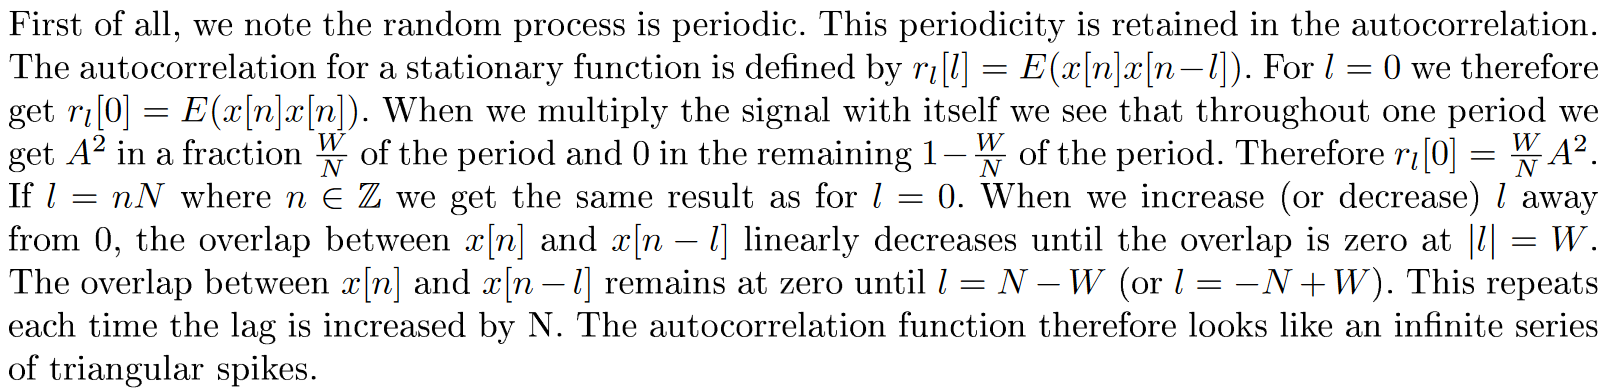

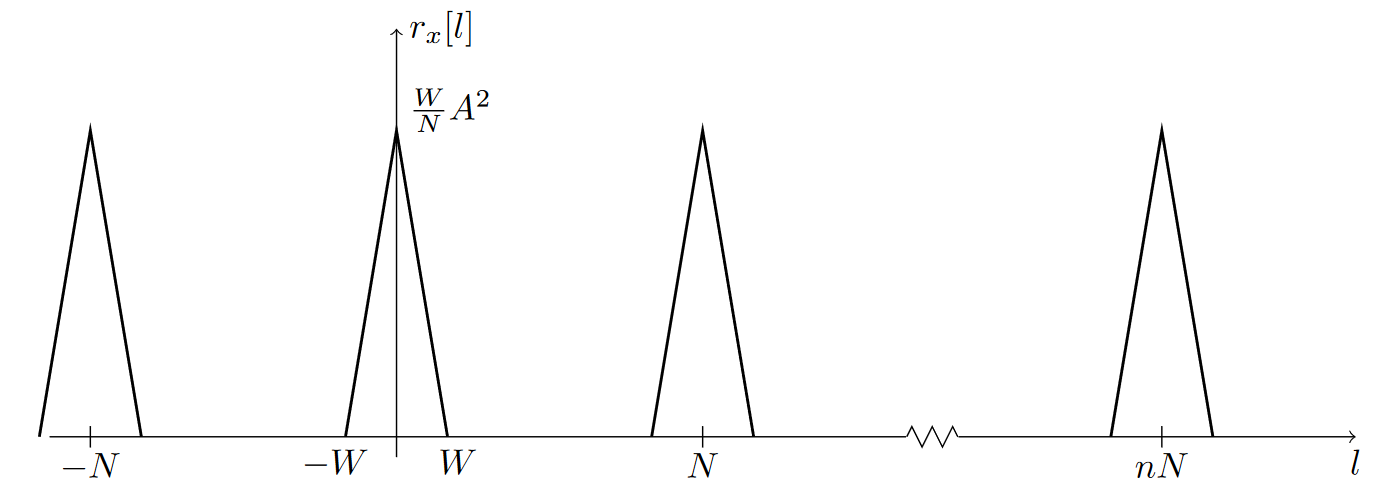

### 2) Use computer simulations to verify the above result

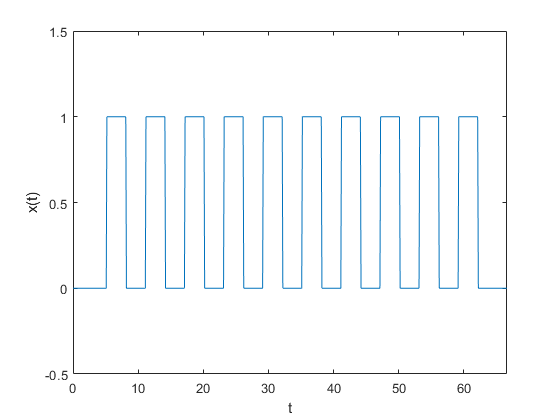

A = 1;
W = 3;  % Pulse width
T = 6; % Period width
N = 10;

% Random number from a uniform distribution in the open interval (a, b)
% a = 0; b = T; random_number = (b-a)*rand + a
phi = T*rand(1);

maxT = phi+W/2 + T*N;

t=0:.1:maxT;   % Time vector 
d= phi+W/2:T:phi+W/2+T*N-1; % Delay vector
y = pulstran(t,d,'rectpuls', W);
plot(t,y)

ylabel('x(t)');
xlabel('t');
ylim([-0.5, A+0.5]);
xlim([0, max(t)]);

Autocorrelation is symmetrical around zero.

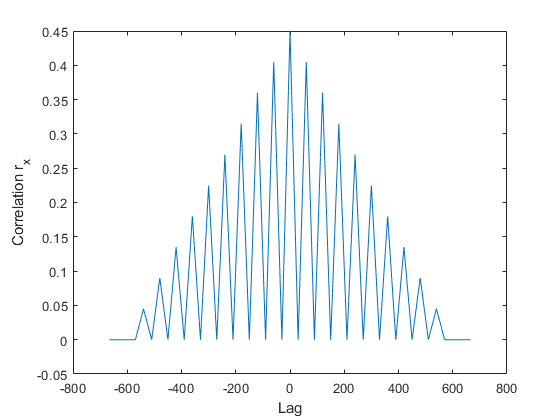

[r_xx, lags] = xcorr(y, 'biased');
plot(lags, r_xx);
ylabel('Correlation r_x');
xlabel('Lag')

## [✔] ADSI Problem 4.4: Autocorrelation of complex signals

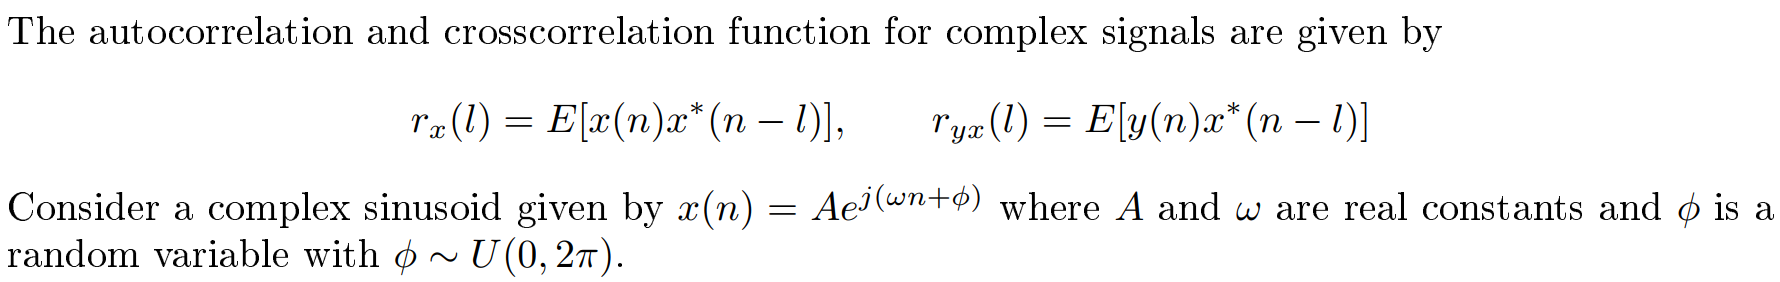

### 1) Compute the analytic expression for the autocorrelation of the complex sinusoid 

The autocorrelation function for complex signals can be computed as:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n-\ell \right)\right\rbrack$$


Plugging the given complex sinusiod into the formula, we get:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack A\;e^{j\left(\omega n+\phi \right)} A\;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$


Since $A$ is a constant, we can move it outside the expected value:


$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\left(\omega n+\phi \right)} \;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi } \;e^{-j\omega n+j\omega \ell -j\phi } \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi +\left(-j\omega n+j\omega \ell -j\phi \right)} \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi -j\omega n+j\omega \ell -j\phi } \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega \ell } \;\right\rbrack$$


We know that $E\left\lbrack e^{j\omega \ell } \right\rbrack =e^{j\omega \ell }$ because the expected value of a constant is just the constant itself. Notice that $\phi$ is no longer in the expression $e^{j\omega \ell }$. Therefore, the autocorrelation of the complex sinusoid is:


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


### 2) How are rx(l) and rx(-l) related for a complex signal?

In 1) we found an analytical expression for $r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell }$

Let us compute the autocorrelation for $-\ell$:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n+\ell \right)\right\rbrack$$


Suppose $m=n+\ell$. Then we can write $n=m-\ell$. Let us substitute all $n$ with $m$ in the above expression:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(m-\ell \right)x^* \left(m\right)\right\rbrack$$


Computing the complex conjucate of the expectation we get:


$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x^* \left(m-\ell \right)x\left(m\right)\right\rbrack }^*$$



$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$$


Since $r_{\textrm{xx}}^* \left(\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$, we know that:


$$r_{\textrm{xx}} \left(-\ell \right)=r_{\textrm{xx}}^* \left(\ell \right)$$


### 3) Compute the autocorrelation of a real cosine signal

We can use the result from 1)


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Since the result from 1) uses Euler, we need to convert the signal to complex exponential. 

We use the relation $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$


$$x\left(n\right)=A\;\mathrm{cos}\left(\omega \;n+\phi \right)$$



$$x\left(n\right)=\frac{A}{2}\;\left(e^{j\left(\omega n+\phi \right)} +e^{-j\left(\omega n+\phi \right)} \right)$$



$$x\left(n\right)=\frac{A}{2}e^{j\left(\omega n+\phi \right)} +\frac{A}{2}e^{-j\left(\omega n+\phi \right)}$$


In 1) we found that the autocorrelation of a complex sinusoid $x\left(n\right)=A\;e^{j\left(\omega \;n+\phi \right)}$ is $r_{\textrm{xx}} \left(\ell \right)=A^2 e^{j\omega \ell }$

Therefore, the autocorrelation of the real signal is:


$$r_{\mathrm{xx}} \left(\ell \right)={\left(\frac{A}{2}\right)}^2 e^{j\omega \ell } +{\left(\frac{A}{2}\right)}^2 e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Using the relation $\cos \left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$  we can rewrite the autocorrelation to:


$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


## [✔] ADSI Problem 4.5: Autocorrelation of distorted signals

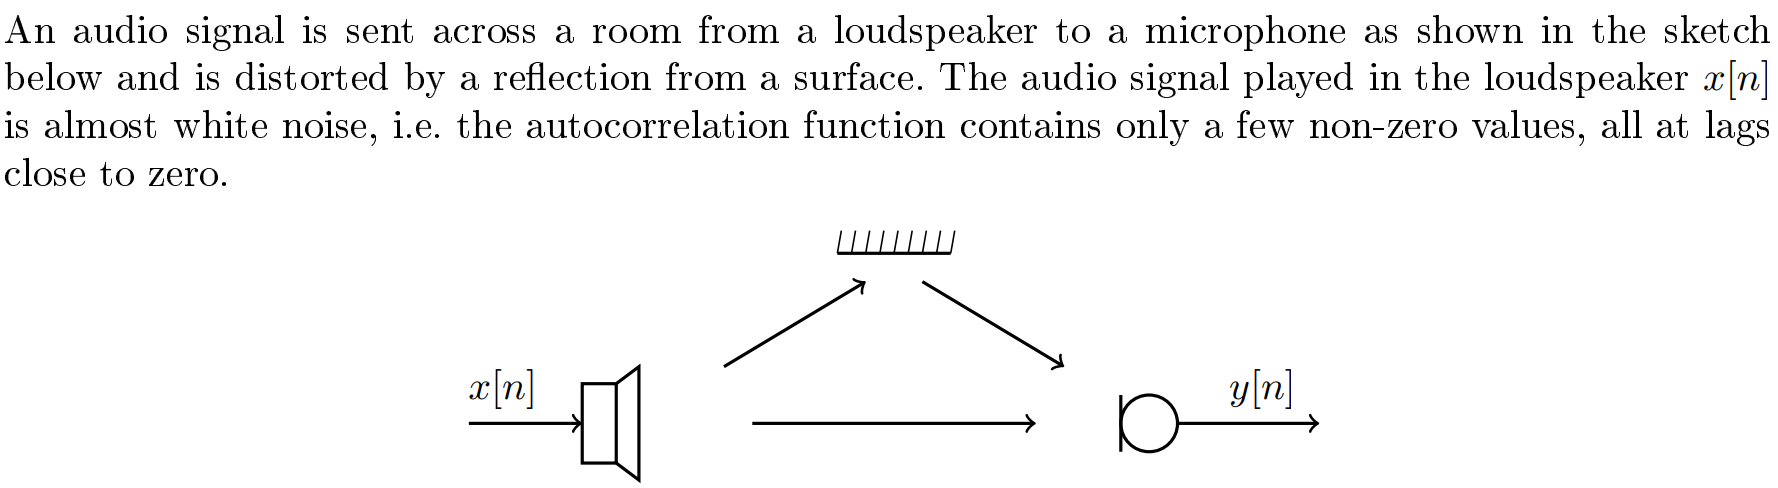

### 1) Derive autocorrelation function of the output signal

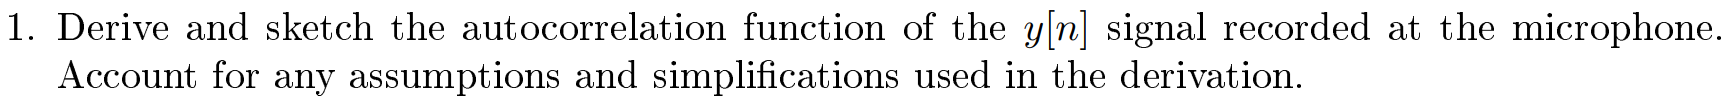

From the figure, we observed that the signal at microphone $y\left(n\right)$ is a combination of two signals.

The bottom arrow describes the signal from the loudspeaker that reaches the microphone with no distortion and no delays.

The two top arrows describes the signal that is distorted by a reflection. This means that the original signal $x\left(n\right)$ will be attenuated and delayed.

Therefore, we can describe the signal at the microphone as

    
$$y\left(n\right)=x\left(n\right)+\alpha x\left(n-D\right)$$


where

- $\alpha <1$ is the attenuation caused by the reflection

- $D$ is the delay of the original signal

The autocorrelation of $y\left(n\right)$ can be derived:

        
$$r_{\mathrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(x\left(n\right)+\alpha x\left(n-D\right)\right)\left(x\left(n-\ell \right)+\alpha x\left(n-D-\ell \right)\right)\right\rbrack$$


Multiple each terms

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)+\alpha x\left(n\right)x\left(n-D-\ell \right)+\alpha x\left(n-D\right)x\left(n-\ell \right)+\alpha^2 x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


Seperate expectation terms

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack \alpha x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +E\left\lbrack \alpha x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack \alpha^2 x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


Move constants out of the expecation:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 E\left\lbrack x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


We will use the relation $r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$ to rewrite the expression above.

The expectation in the first term and the last term are trivial to rewrite:

        
$$r_{\textrm{yy}} \left(\ell \right)=r_{\mathrm{xx}} \left(\ell \right)+\alpha E\left\lbrack x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 r_{\mathrm{xx}} \left(\ell \right)$$


We know that $r_{\textrm{xx}} \left(\ell -D\right)=E\left\lbrack x\left(n\right)x\left(n-\ell -D\right)\right\rbrack$ so we want rewrite the second term:

        
$$r_{\textrm{yy}} \left(\ell \right)=r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 r_{\textrm{xx}} \left(\ell \right)$$


Let $m=n-D$ then $n=m+D$. Then $E\left\lbrack x\left(m\right)x\left(m-\ell +D\right)\right\rbrack$. Thus, the third term can rewritten to:

        
$$r_{\textrm{yy}} \left(\ell \right)=r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha r_{\mathrm{xx}} \left(\ell +D\right)+\alpha^2 r_{\textrm{xx}} \left(\ell \right)$$


To make it easier to sketch the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$, we can rewrite it the expression as:

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(1+\alpha^2 \right)r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha r_{\textrm{xx}} \left(\ell +D\right)$$


From this expression, we know that there are three peaks because each autocorrelation $r_{\mathrm{xx}}$ corresponds to a peak. One peak is at lag zero, another peak at lag $-D$ and the last peak at $D$. Therefore, 

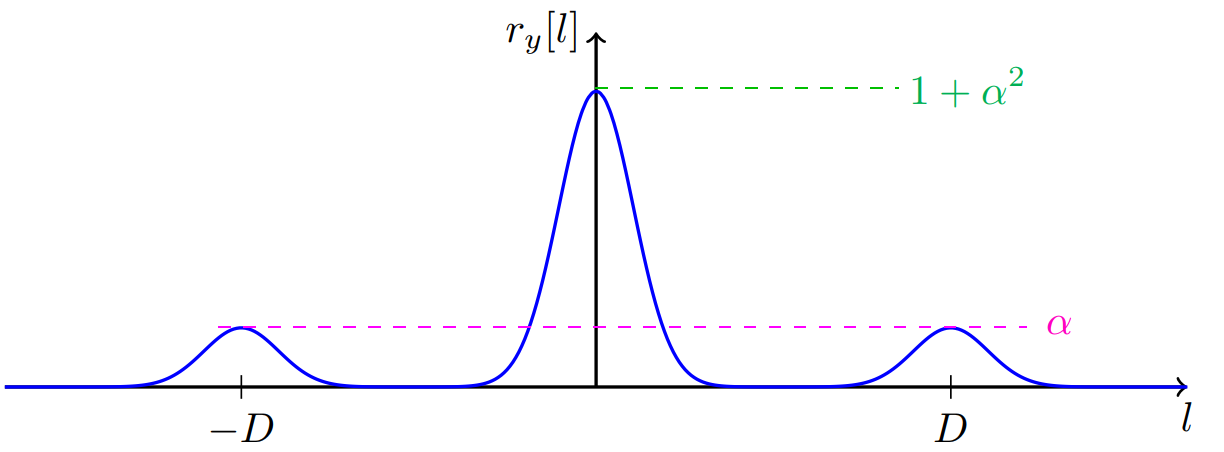

Let us check if we can see the same patterns if we simulate it in MATLAB:

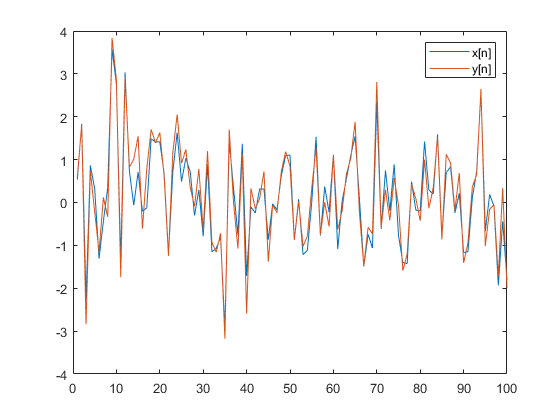

alpha = 0.3;
D = 5;
N = 100;

n = [1:N];
x = wgn(N,1,0);
y = x + alpha*circshift(x, D);
plot(n, x, n, y)
legend('x[n]', 'y[n]')

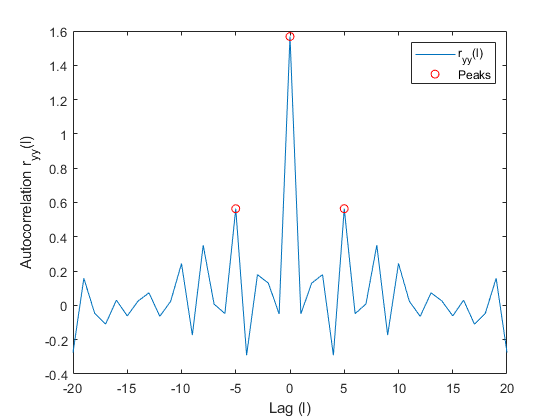

[r_yy, lags] = xcorr(y, 20, 'biased');
plot(lags, r_yy);
hold on;
plot(0, r_yy(find(lags == 0)), 'ro');
plot(D, r_yy(find(lags == D)), 'ro');
plot(-D, r_yy(find(lags == -D)), 'ro');
legend('r_{yy}(l)', 'Peaks')
ylabel('Autocorrelation r_{yy}(l)');
xlabel('Lag (l)')
hold off;

### 2) Is possible to remove the distortion from the output signal?

The distoration corresponds to a FIR filter with the system function $H\left(z\right)=1+\alpha z^{-D}$. In principle, we can remove this distoration with an inverse system:


$$\frac{1}{1+\alpha z^{-D} }$$


However, if we want to implement such an inverse system, we have to build IIR filter.

We might not want to do that. The poor man's approach is as follows:

From our sketch, we can estimate the delay and attenuation by the position of the peaks and the amplitude ratio.

Then we create a FIR filter which substract a delayed and attenuated copy of $y\left\lbrack n\right\rbrack$:


$$z\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack -\alpha y\left\lbrack n-D\right\rbrack$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha \left(x\left\lbrack n-D\right\rbrack +\alpha x\left\lbrack \left(n-D\right)-D\right\rbrack \right)$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha \left(x\left\lbrack n-D\right\rbrack +\alpha x\left\lbrack n-2D\right\rbrack \right)$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha x\left\lbrack n-D\right\rbrack -\alpha^2 x\left\lbrack n-2D\right\rbrack$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -\alpha^2 x\left\lbrack n-2D\right\rbrack$$


The result is a new signal $z\left\lbrack n\right\rbrack$ where the distortion is pushed to $2D$ and the attenuation factor is squared. 

Since $\alpha <1$, the squared attenuation $\alpha^2$ is much smaller than 1. This means the distortion component is much smaller than before.

## ADSI Problem 4.6: System identification using ARMA(2,2) as input

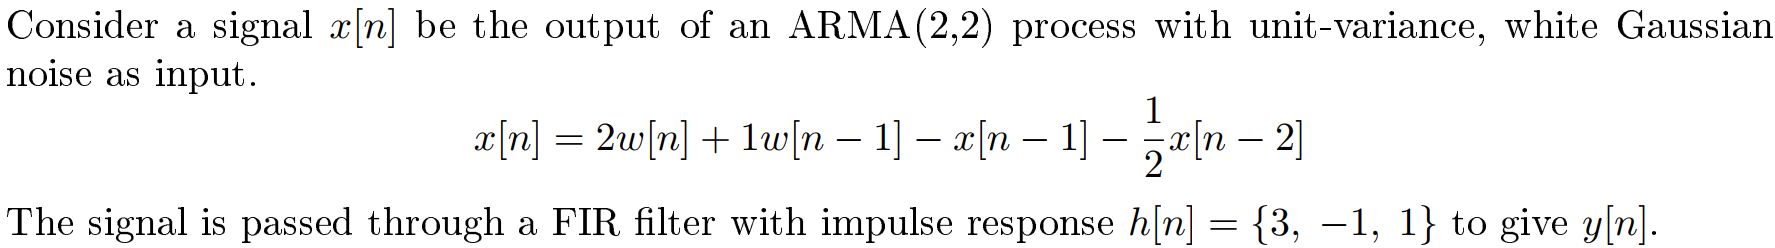

clear variables;
clear figure;

### 1) Simulate the autocorrelation and cross-correlation in MATLAB

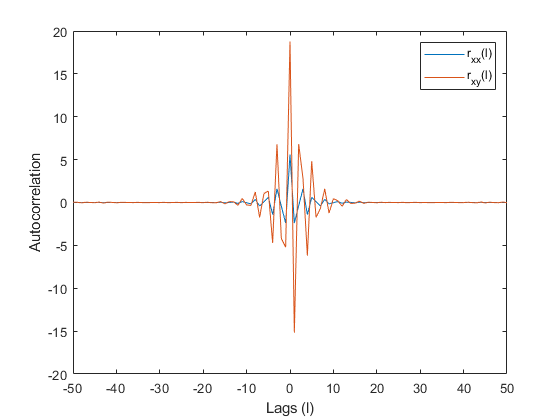

w=randn(1e6,1);
x=filter([2 1],[1 1 0.5],w);
y=filter([3 -1 1],1,x);

[rxx,lagsrxx]=xcorr(x,50,'biased');
[ryx,lagsryx]=xcorr(y,x,50,'biased');


plot(lagsrxx, rxx, lagsryx, ryx)
xlabel('Lags (l)')
ylabel('Autocorrelation')
legend('r_{xx}(l)', 'r_{xy}(l)')

### 2) Compute the transfer function and impulse response from the autocorrelation

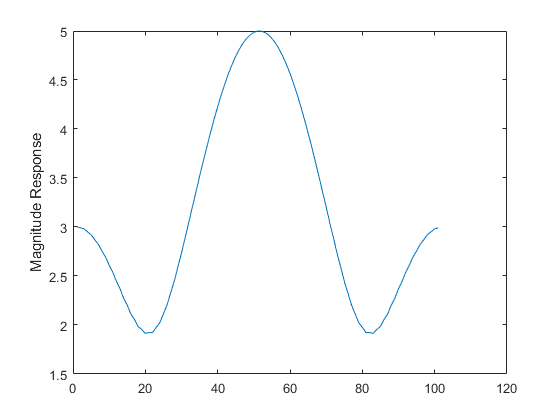


Rxx=fft(rxx);
Ryx=fft(ryx);
H=Ryx./Rxx;
plot(abs(H))
ylabel('Magnitude Response')

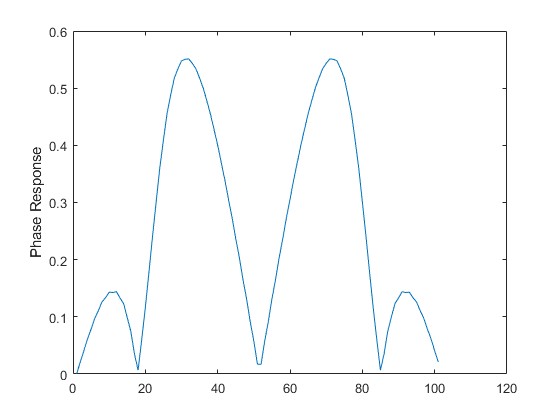


plot(abs(angle(H)))
ylabel('Phase Response')

Compute the impulse response:

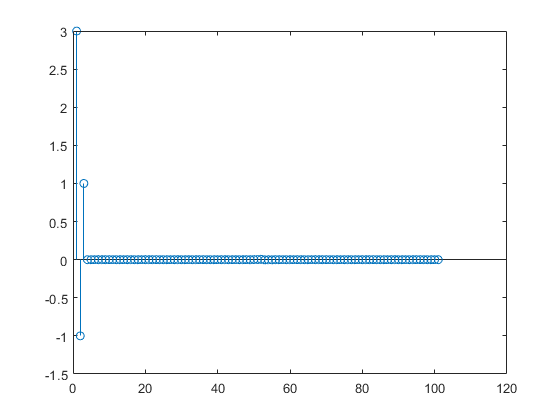

h = ifft(H);
stem(real(h))